# Analysis of Voltages

## This program will perform statisticall analysis on a time series of voltages



v_measurements =  [21.2, 19.5, 20.1, 18.3, 17.7, 15.0, 21.9, 24.7, 23.1, 20.2, 16.3, 22.8, 18.4, 23.5, 21.1]

v_measurements =    21.2000   19.5000   20.1000   18.3000   17.7000   15.0000   21.9000   24.7000   23.1000   20.2000   16.3000   22.8000   18.4000   23.5000   21.1000



% (1) Minimum 
v_min = min(v_measurements)

v_min = 15

fprintf("Average Voltage: %.2f\n",v_min)

Average Voltage: 15.00



% (2) Maximum
v_max = max(v_measurements)

v_max = 24.7000

fprintf("Max Voltage: %.2f\n",v_max)

Max Voltage: 24.70



% (3) Average
v_avg = mean(v_measurements)

v_avg = 20.2533

fprintf("Average Voltage: %.2f\n",v_avg)

Average Voltage: 20.25



% (4) Std. Deviation
v_std = std(v_measurements)

v_std = 2.7622

fprintf("Std. Deviation of Voltages: %.2f\n",v_std)

Std. Deviation of Voltages: 2.76



% (5) Median 
v_med = median(v_measurements)

v_med = 20.2000

fprintf("Median Voltage: %.2f\n",v_med)

Median Voltage: 20.20



% (6) Num. Values > Avg 
num_vals_greater_than_avg = sum(v_measurements>v_avg)

num_vals_greater_than_avg = 7

fprintf("Number of Voltage Values > %.2f: %.f\n",v_avg, num_vals_greater_than_avg)

Number of Voltage Values > 20.25: 7



% (7) Values > Avg 
v_greater_than_avg = v_measurements(v_measurements > v_avg)

v_greater_than_avg =    21.2000   21.9000   24.7000   23.1000   22.8000   23.5000   21.1000


fprintf("Voltage Greater than Average: %.2f\n", v_greater_than_avg)

Voltage Greater than Average: 21.20
Voltage Greater than Average: 21.90
Voltage Greater than Average: 24.70
Voltage Greater than Average: 23.10
Voltage Greater than Average: 22.80
Voltage Greater than Average: 23.50
Voltage Greater than Average: 21.10


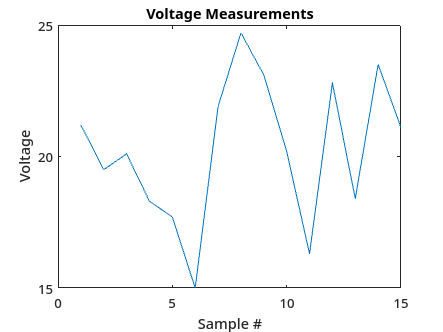

% (8) Raw Plot 

plot(v_measurements)
title('Voltage Measurements')
xlabel('Sample #')
ylabel('Voltage')

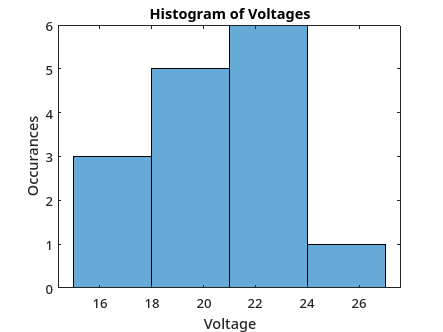


% (9) Histogram 
histogram(v_measurements)
title('Histogram of Voltages')
xlabel('Voltage')
ylabel('Occurances')


% (10) Sorted 
v_sorted = sort(v_measurements)

v_sorted =    15.0000   16.3000   17.7000   18.3000   18.4000   19.5000   20.1000   20.2000   21.1000   21.2000   21.9000   22.8000   23.1000   23.5000   24.7000



% printing sorted measurements in new lines 
disp("Voltages in sorted order: ")

Voltages in sorted order: 


for i = 1:length(v_sorted)
    fprintf("%.2f\n", v_sorted(i)); 
end

15.00
16.30
17.70
18.30
18.40
19.50
20.10
20.20
21.10
21.20
21.90
22.80
23.10
23.50
24.70
